clc
clear all

Acquire data

d = daqlist("ni")

d = 1×4 table
    DeviceID                       Description                                Model                   DeviceInfo      
    ________    _________________________________________________    ________________________    _____________________

     "Dev1"     "National Instruments(TM) USB-6356 (32 MS) (BNC)"    "USB-6356 (32 MS) (BNC)"    1×1 daq.ni.DeviceInfo



dq = daq("ni");
dq.Rate = 1000000;
addinput(dq, "Dev1", "ai0", "Voltage");
addinput(dq, "Dev1", "ai1", "Voltage");
addinput(dq, "Dev1", "ai2", "Voltage");
addinput(dq, "Dev1", "ai3", "Voltage");

data = read(dq, seconds(15));

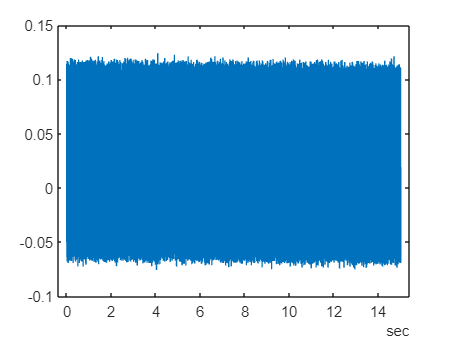

plot(data.Time, data.Dev1_ai3)

Check the trigger sensor's output

%Discover Analog Input Devices
d = daqlist("ni")

d = 1×4 table
    DeviceID                       Description                                Model                   DeviceInfo      
    ________    _________________________________________________    ________________________    _____________________

     "Dev1"     "National Instruments(TM) USB-6356 (32 MS) (BNC)"    "USB-6356 (32 MS) (BNC)"    1×1 daq.ni.DeviceInfo



%Create a DataAcquisition object for NI devices
dq = daq("ni");

dq.Rate = 1000000;
addinput(dq, "Dev1", "ai0", "Voltage");
addinput(dq, "Dev1", "ai1", "Voltage");
addinput(dq, "Dev1", "ai2", "Voltage");
addinput(dq, "Dev1", "ai3", "Voltage");
addinput(dq, "Dev1", "ai4", "Voltage");

Spindata = read(dq,seconds(0.25));
TriggerOut = Spindata(:,5);
TriggerOut = transpose(table2array(TriggerOut));
SpinCheck = mean(TriggerOut)

SpinCheck = 2.2030


while SpinCheck > 0.3 && SpinCheck < 4.722
    Spindata = read(dq, seconds(0.25));
    TriggerOut = Spindata(:,5);
    TriggerOut = transpose(table2array(TriggerOut));
    SpinCheck = mean(TriggerOut)
end

SpinCheck = 2.1465

SpinCheck = 2.1068

SpinCheck = 2.1072

SpinCheck = 2.1040

SpinCheck = 2.1025

SpinCheck = 2.1089

SpinCheck = 2.1022

SpinCheck = 2.1085

SpinCheck = 2.1010

SpinCheck = 2.1032

SpinCheck = 2.0894

SpinCheck = 2.0867

SpinCheck = 2.0882

SpinCheck = 2.0997

SpinCheck = 2.0091

SpinCheck = 1.7628

SpinCheck = 1.7494

SpinCheck = 1.7539

SpinCheck = 1.7418

SpinCheck = 1.7385

SpinCheck = 1.7291

SpinCheck = 1.7332

SpinCheck = 1.7248

SpinCheck = 1.7254

SpinCheck = 1.7221

SpinCheck = 1.7292

SpinCheck = 1.7186

SpinCheck = 1.7250

SpinCheck = 1.7199

SpinCheck = 1.7194

SpinCheck = 1.7229

SpinCheck = 1.7168

SpinCheck = 1.7208

SpinCheck = 1.7173

SpinCheck = 1.7339

SpinCheck = 1.7837

SpinCheck = 2.0712

SpinCheck = 2.0907

SpinCheck = 2.1732

SpinCheck = 2.1960

SpinCheck = 2.1994

SpinCheck = 2.1847

SpinCheck = 2.1842

SpinCheck = 2.1829

SpinCheck = 2.1898

SpinCheck = 2.1891

SpinCheck = 2.1994

SpinCheck = 2.1846

SpinCheck = 2.2000

SpinCheck = 2.1839

SpinCheck = 2.1844

SpinCheck = 2.1868

SpinCheck = 2.1661

SpinCheck = 1.9555

SpinCheck = 1.7446

SpinCheck = 1.7217

SpinCheck = 1.7024

SpinCheck = 1.7023

SpinCheck = 1.6615

SpinCheck = 1.6578

SpinCheck = 1.6586

SpinCheck = 1.6579

SpinCheck = 1.6552

SpinCheck = 1.6494

SpinCheck = 1.6475

SpinCheck = 1.6488

SpinCheck = 1.6474

SpinCheck = 1.6459

SpinCheck = 1.6448

SpinCheck = 1.6745

SpinCheck = 2.0382

SpinCheck = 2.0543

SpinCheck = 4.9499

Check the tool image

%Aquire image through Webcam
webcamlist

ans = 2×1 cell array
    {'MD35'        }
    {'UTP200X003MP'}


cam = webcam(2)

cam =   webcam with properties:

                     Name: 'UTP200X003MP'
     AvailableResolutions: {'640x480'  '320x240'  '160x120'}
               Resolution: '640x480'
             WhiteBalance: 4000
                      Hue: 0
               Brightness: 0
               Saturation: 32
         WhiteBalanceMode: 'auto'
                    Gamma: 100
             ExposureMode: 'auto'
    BacklightCompensation: 0
                 Exposure: -5
                 Contrast: 32
                Sharpness: 1


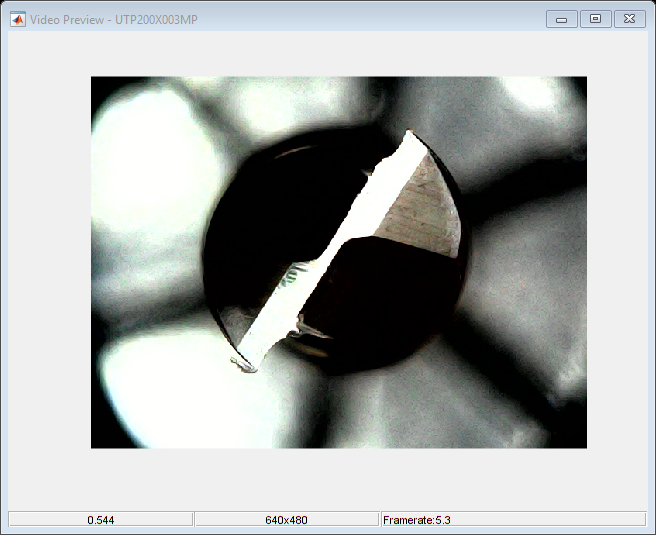

%img = snapshot(cam);
%imwrite(img,"T1New4.png")
%G20G1X-2.2Z2.62F75 
preview(cam)